close all
clear all
clc

## Sistema original (lazo cerrado)

G = tf([0 0 16],[1 4 0]);
GH = feedback(G,1);

## Controlador de atraso

zc = -0.02; 		        
pc = -0.00248; 		    
kc = 1.0022;                   
Gc = zpk(zc,pc,kc)	

Gc =
 
  1.0022 (s+0.02)
  ---------------
    (s+0.00248)
 
Continuous-time zero/pole/gain model.



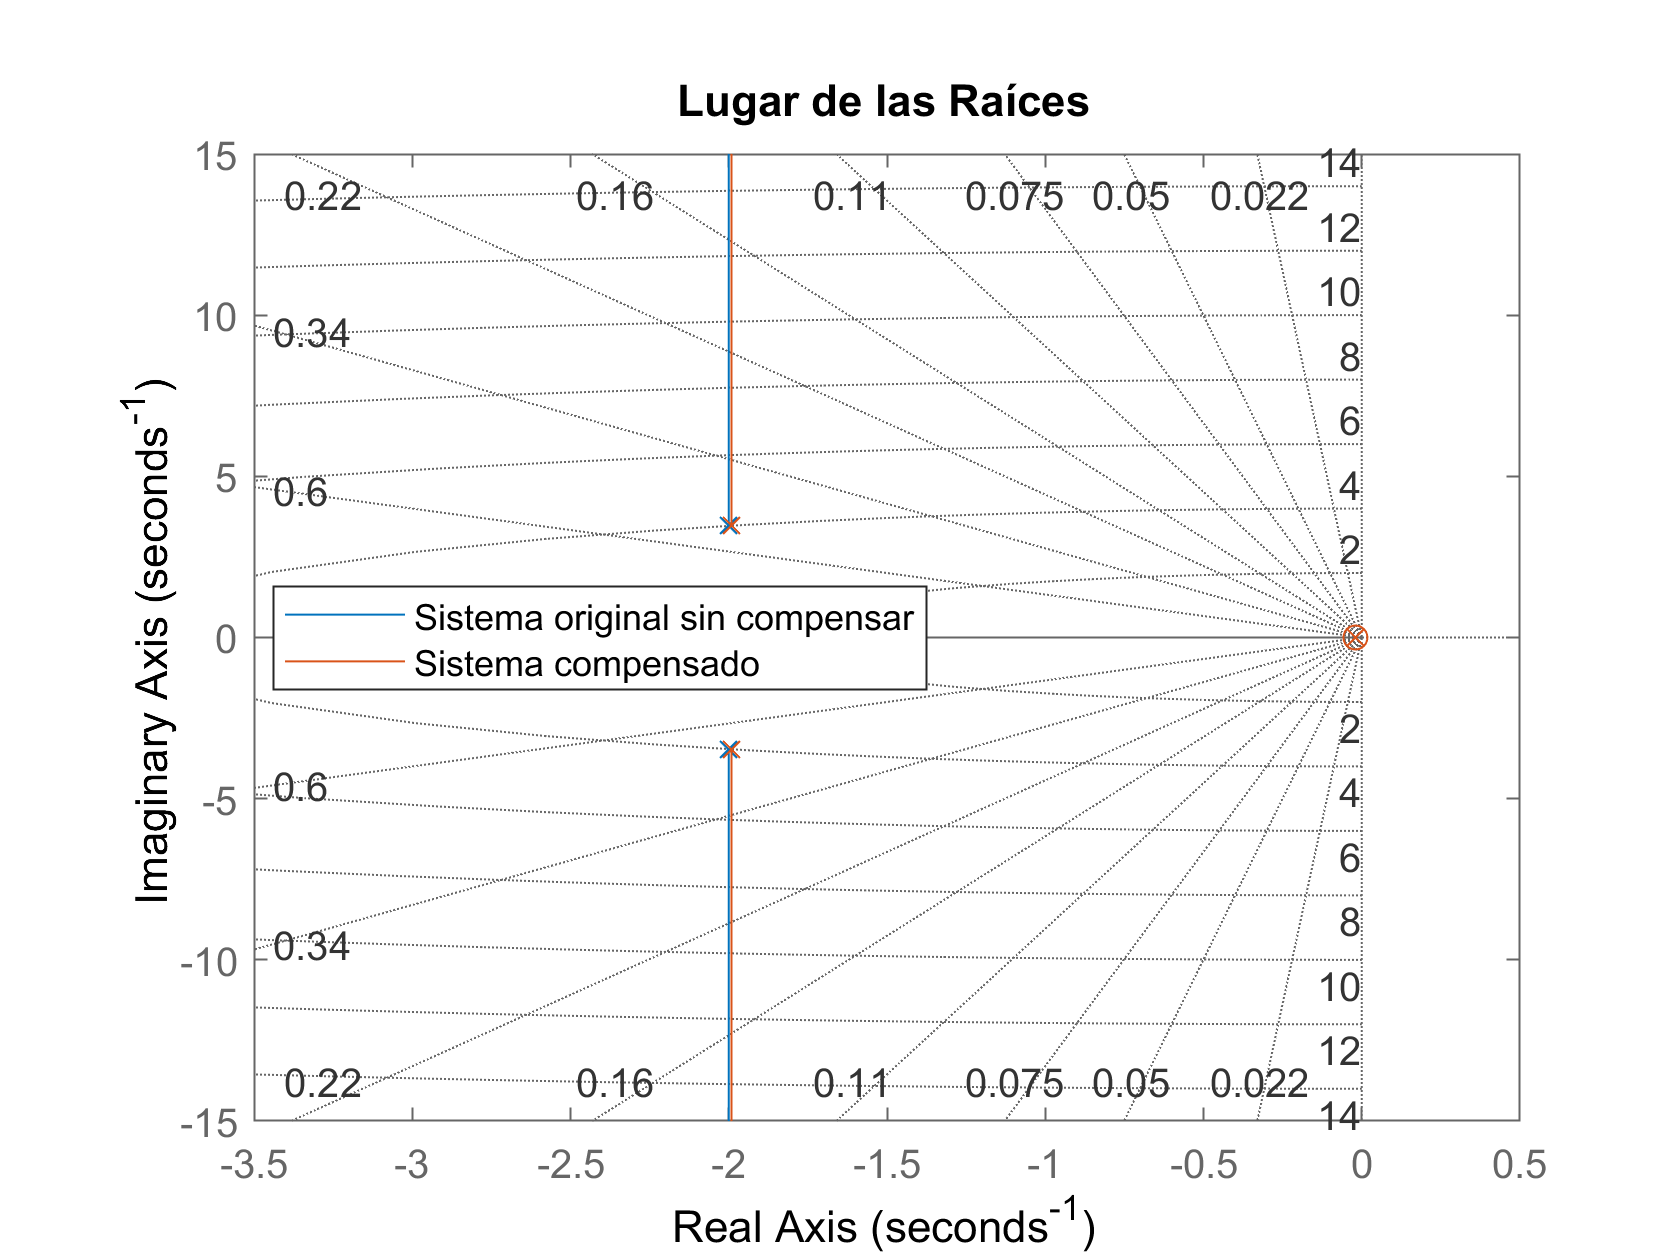

GcG = G*Gc;
GcGH = feedback(GcG,1);

rlocus(GH, GcGH)
legend('Sistema original sin compensar','Sistema compensado','location','best');
title('Lugar de las Raíces')
grid on

## Respuestas al escalón

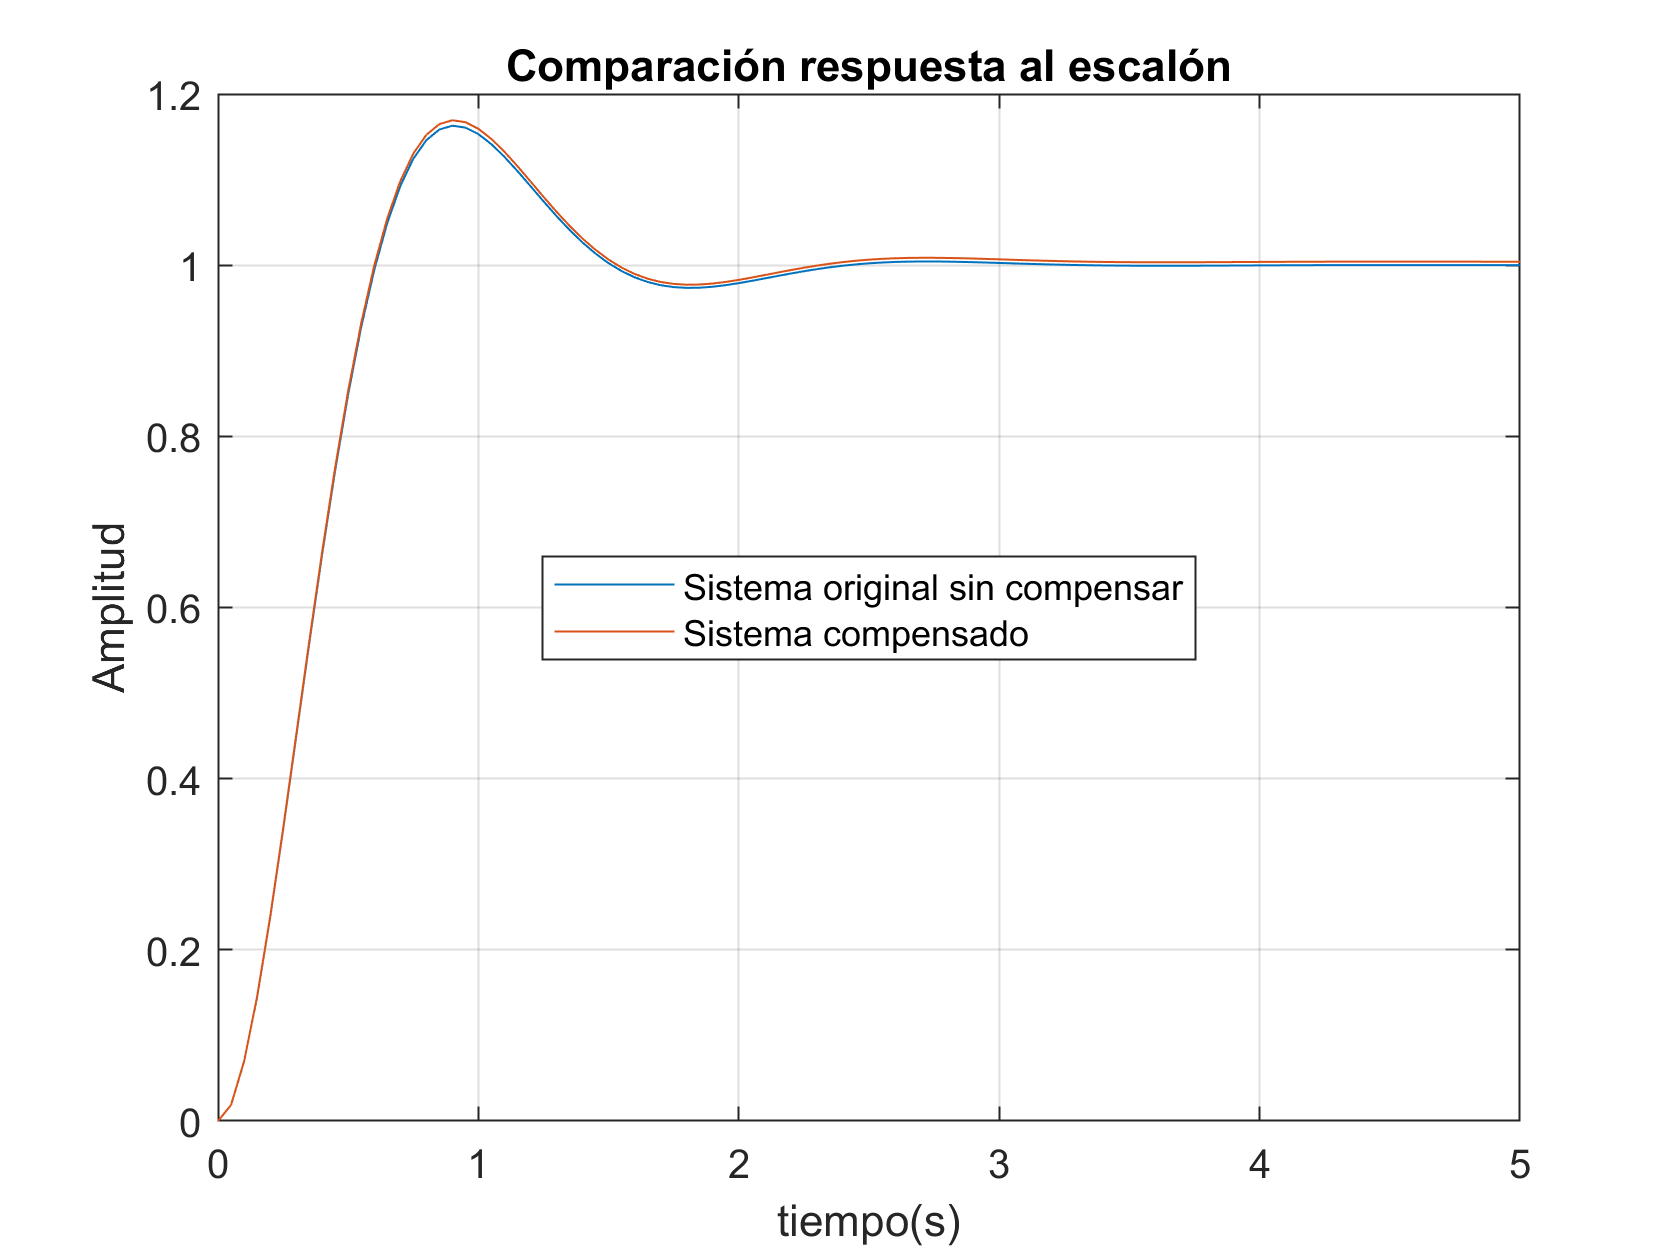

t=0:0.05:5;
sys = step(GH,t);
sysc = step(GcGH,t);
plot(t,sys,t,sysc)
legend('Sistema original sin compensar','Sistema compensado','location','best');
title('Comparación respuesta al escalón')
xlabel('tiempo(s)')
ylabel('Amplitud')
grid on

## Respuestas a la rampa

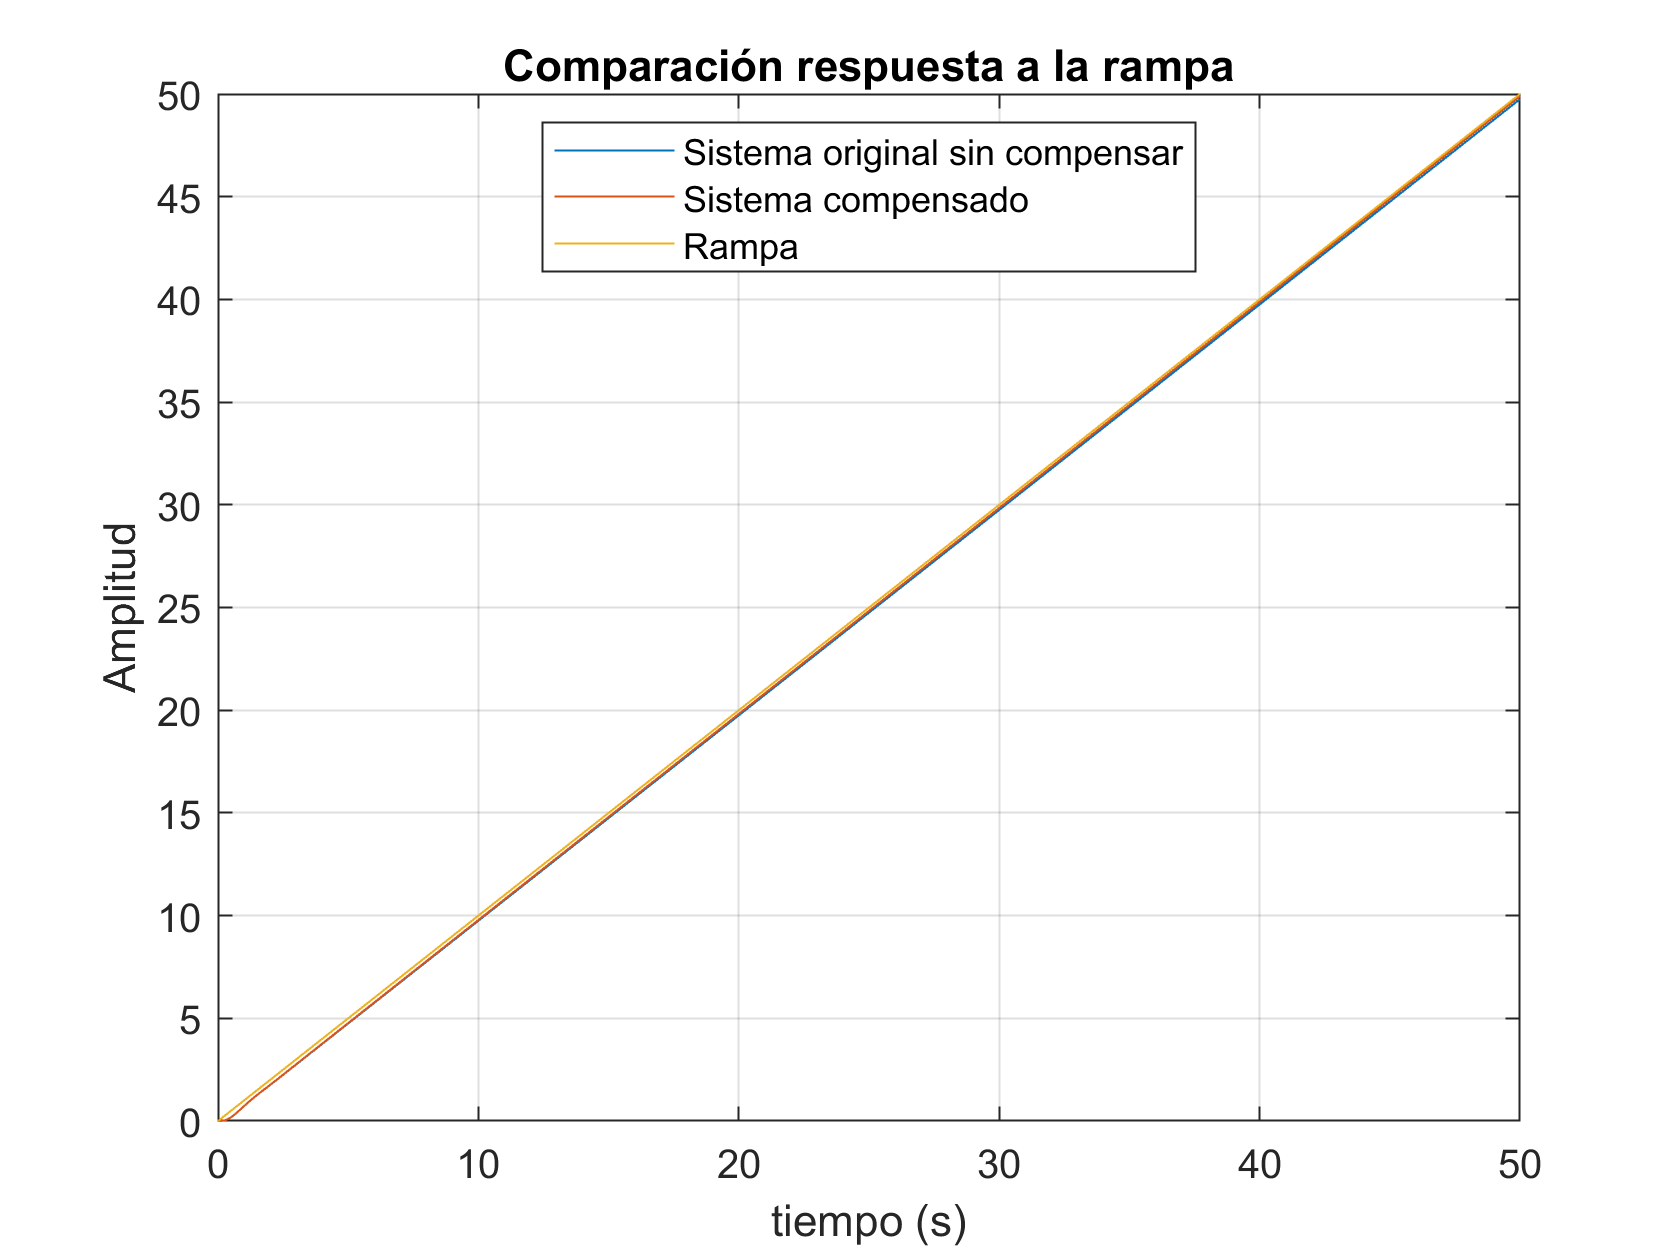

s = tf([0 1],[1 0]);
t=0:0.05:50;
sys = step(GH*s,t);
sysc = step(GcGH*s,t);
plot(t,sys,t,sysc,t,t)
legend('Sistema original sin compensar','Sistema compensado','Rampa','location','best');
title('Comparación respuesta a la rampa')
xlabel('tiempo (s)')
ylabel('Amplitud')
grid on